clear();

# **1 - Optimisation mono-objectif**

## **    1.1) Initialisation des constantes du problème**

            **1.1.1) Demande et Production**

% nom des fichiers de data
filename_prod_PV2005 = 'Ppv_kWc_inst_castres_Pdata_2005.csv';
filename_demande = 'demande.csv';

% extraire le contenu du fichier pour qu'il soit exploitable dans Matlab
data_prod = readtable(filename_prod_PV2005);
data_demande = readtable(filename_demande);

% convertir la table en array
production = table2array(data_prod(:,1)); 
demande = table2array(data_demande(:,4))/1000; % convertir la demande en kWh

        **1.1.2) Données de l'énoncé**

% cout = [Cpv, Cel, Cpac, Cbat, Cext]
cout = [1200, 2000, 1000, 400, 2];

% rendement = [Nel, Npac]
rendement = [0.5 0.6];
n = 20; % Nombre d'années pour l'étude du problème
dureVieBatterie = 10; % La durée de vie d'une batterie est de 10 ans

## **    1.2) Résolution mono-objectif**

            **1.2.1) Test de la fonction mono-objectif**

% Exemple d'utilisation de la function cout
x0 = [0.8 0.5 0.5 0.8];
[couTot] = funCout(x0, demande, production, cout, dureVieBatterie, rendement, n)

couTot = 3.4208e+05

% couTot représente le cout total en euro de l'installation et de la consommation
% sur n années

            **1.2.2) Résolution**

paramin = [0 0 0 0];
probleme = createOptimProblem('fmincon', 'x0', x0, 'objective', @(x) funCout(x, demande, production, cout, dureVieBatterie, rendement, n), 'lb',paramin);
% résolution par la methode multistart
ms = MultiStart();
[x, fval, exitflag, output, solutions] = run(ms, probleme, 10);

MultiStart completed the runs from all start points.

All 10 local solver runs converged with a positive local solver exit flag.


nvars = 4;
[x2,fval2,exitflag2,output2,population,scores] = ga(@(x) funCout(x, demande, production, cout, dureVieBatterie, rendement, n),nvars,[],[],[],[],paramin,[],[],[]);

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


Qext = zeros(1,length(demande)); % quantité d'énergie achetée sur le réseau
Qbat = zeros(1,length(demande)); % stock d'énergie dans la batterie
Qh2 = zeros(1,length(demande)); % stock d'énergie dans la PAC
consoH2 = zeros(1,length(demande));
Qbat(1) = 0;
Qh2(1) = 0;
Qext(1) = demande(1) - production(1);
consoH2(1) = 0

consoH2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Qext2 = zeros(1,length(demande)); % quantité d'énergie achetée sur le réseau
Qbat2 = zeros(1,length(demande)); % stock d'énergie dans la batterie
Qh22 = zeros(1,length(demande)); % stock d'énergie dans la PAC
consoH22 = zeros(1,length(demande));
Qbat2(1) = 0;
Qh22(1) = 0;
Qext2(1) = demande(1) - production(1);
consoH22(1) = 0

consoH22 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


% chaque jour, maj de l'état du systeme
% x = [Spv, Pel, Ppac, Qbat]


## Lignes de code pour tracer les courbes du premier solveur


for heure = 2:length(demande)
    excedent = production(heure)*x(1)-demande(heure);
    % Cas d'une surproduction PV
    if excedent >= 0
        Qbat(heure) = Qbat(heure-1) + min(excedent, x(4)-Qbat(heure-1));
        excedent2 = max(0, excedent-Qbat(heure));
        nrjAElectrolyser = min(excedent2, x(2));
        Qh2(heure) = Qh2(heure-1) + nrjAElectrolyser * rendement(1);
        %Qext(heure) = nrjAElectrolyser - excedent2;  % <=0 car on revend l'excedent d'énergie au réseau
        Qext(heure) = 0;
        consoH2(heure) = 0;
    % Cas d'une sous-production PV
    else
        manque = -excedent;
        nrjFourniBat = min(Qbat(heure - 1), manque);
        Qbat(heure) = Qbat(heure -1)-nrjFourniBat;
        manque2 = max(0, manque-nrjFourniBat);
        nrjAFournirH2 = min(x(3),min(Qh2(heure-1)*rendement(2), manque2));
        Qh2(heure) = Qh2(heure-1)-nrjAFournirH2 / rendement(2);
        Qext(heure) = manque2 - nrjAFournirH2;  % >=0 car on achete de l'énergie au réseau
        consoH2(heure) = nrjAFournirH2;
    end
end
abscisse = 1:length(demande)

abscisse =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


## Lignes de code pour tracer les courbes du deuxième solveur

for heure = 2:length(demande)
    excedent = production(heure)*x2(1)-demande(heure);
    % Cas d'une surproduction PV
    if excedent >= 0
        Qbat2(heure) = Qbat2(heure-1) + min(excedent, x2(4)-Qbat2(heure-1));
        excedent2 = max(0, excedent-Qbat2(heure));
        nrjAElectrolyser = min(excedent2, x2(2));
        Qh22(heure) = Qh22(heure-1) + nrjAElectrolyser * rendement(1);
        %Qext(heure) = nrjAElectrolyser - excedent2;  % <=0 car on revend l'excedent d'énergie au réseau
        Qext2(heure) = 0;
        consoH22(heure) = 0;
    % Cas d'une sous-production PV
    else
        manque = -excedent;
        nrjFourniBat = min(Qbat2(heure - 1), manque);
        Qbat2(heure) = Qbat2(heure -1)-nrjFourniBat;
        manque2 = max(0, manque-nrjFourniBat);
        nrjAFournirH2 = min(x2(3),min(Qh22(heure-1)*rendement(2), manque2));
        Qh22(heure) = Qh22(heure-1)-nrjAFournirH2 / rendement(2);
        Qext2(heure) = manque2 - nrjAFournirH2;  % >=0 car on achete de l'énergie au réseau
        consoH22(heure) = nrjAFournirH2;
    end
end
Qext

Qext =     1.2462    1.1050    1.0116    0.9321    0.8990    0.9032    0.9401    1.0279    0.8197         0         0         0         0         0         0    0.1423    1.4545    1.6553    1.8594    2.0194    1.9588    1.7259    1.4850    1.2712    1.1139    0.9980    0.9432    0.9112    0.9085    0.9228    0.9840    1.1128    0.9710    0.5567         0         0         0         0         0         0         0         0         0         0         0         0    1.3119    1.3352    1.1492    1.0210


fval

fval = 7.3718e+04

fval2

fval2 = 7.7253e+04

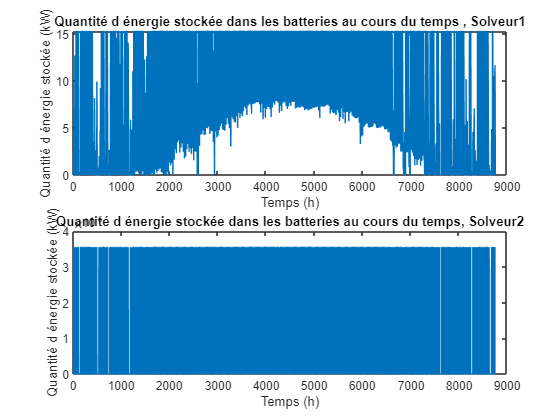

figure(1)
subplot(2,1,1)
plot(abscisse, Qbat)
title('Quantité d énergie stockée dans les batteries au cours du temps , Solveur1');
ylabel('Quantité d énergie stockée (kW)');
xlabel('Temps (h)');
subplot(2,1,2)
plot(abscisse, Qbat2)
title('Quantité d énergie stockée dans les batteries au cours du temps, Solveur2');
ylabel('Quantité d énergie stockée (kW)');
xlabel('Temps (h)');

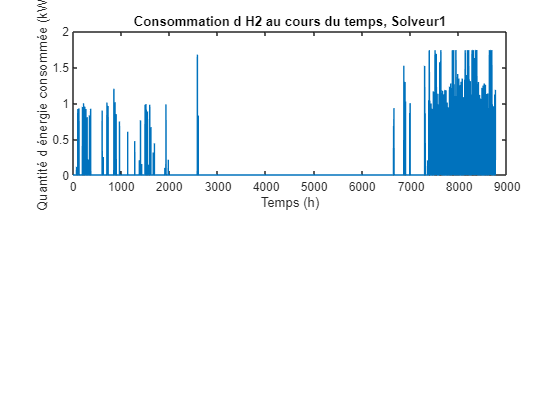

figure(2)
subplot(2,1,1)
plot(abscisse, consoH2)
title('Consommation d H2 au cours du temps, Solveur1');
ylabel('Quantité d énergie consommée (kW)');
xlabel('Temps (h)');

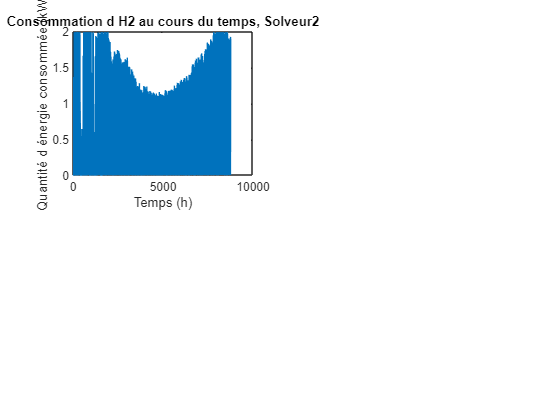

subplot(2,2,1)
plot(abscisse, consoH22)
title('Consommation d H2 au cours du temps, Solveur2');
ylabel('Quantité d énergie consommée (kW)');
xlabel('Temps (h)');

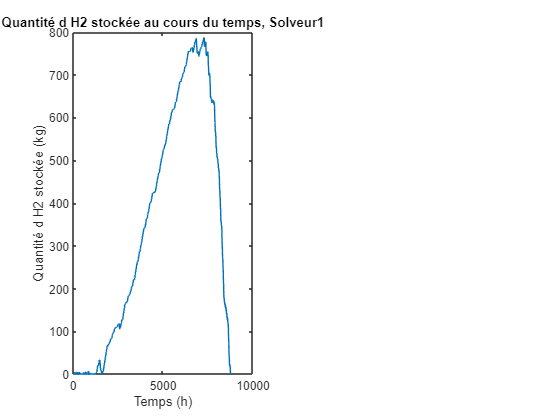

figure(3)
subplot(1,2,1)
plot(abscisse, Qh2)
title('Quantité d H2 stockée au cours du temps, Solveur1');
ylabel('Quantité d H2 stockée (kg)');
xlabel('Temps (h)');

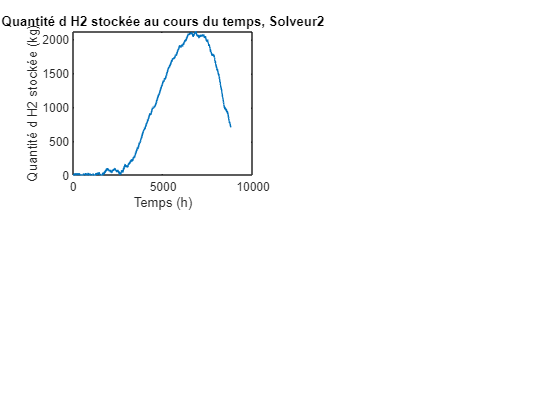

subplot(2,2,1)
plot(abscisse, Qh22)
title('Quantité d H2 stockée au cours du temps, Solveur2');
ylabel('Quantité d H2 stockée (kg)');
xlabel('Temps (h)');

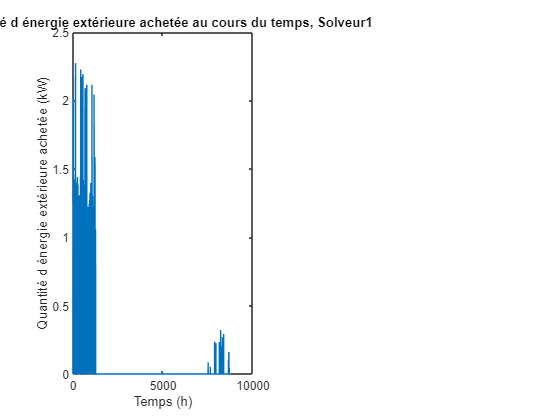

figure(4)
subplot(1,2,1)
plot(abscisse, Qext)
title('Quantité d énergie extérieure achetée au cours du temps, Solveur1');
ylabel('Quantité d énergie extérieure achetée (kW)');
xlabel('Temps (h)');

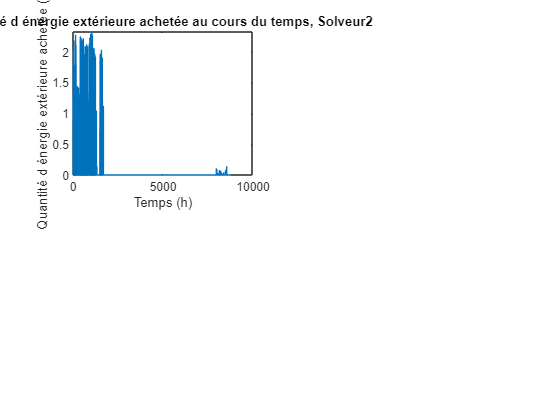

subplot(2,2,1)
plot(abscisse, Qext2)
title('Quantité d énergie extérieure achetée au cours du temps, Solveur2');
ylabel('Quantité d énergie extérieure achetée (kW)');
xlabel('Temps (h)');

## Analyse

La résolution via multistart change une fois sur 3 (faire tourner le résultat plusieurs fois pour analyser ce défaut), tandis que l'algorithme de génétique lui nous renvoie toujours le même résultat. Le reste du temps, multistart nous renvoie les mêmes résultats que l'algorithme génétique.

Nous pouvons supposer que le solveur génétique ne parvient pas à résoudre le problème car les paramètres ne sont pas optimisés, tandis que l'algorithme multistart reussi de temps en temps à nous proposer un résultat cohérent et le reste du temps il ne parvient pas non plus à résoudre le problème. 

Etudions les résultats de l'algorithme multistart : 

L'algorithme génétique nous propose de nous concentrer uniquement sur un système de stockage (ici

H2).

Durant la période d'été (centre des figures) notre consommation d'hydrogène diminue. En effet, notre production d'énergie photovoltaïque agmente alors que la demande diminue. 

 En changeant les paramètres initiaux relatifs aux coûts d'installation de batterie

On remarque également que les deux solveurs nous proposent une stratégie

différente. Celui basé sur de la recherche multistart nous propose de

mettre en place à la fois un système de stockage à l'aide de batteries ET un système de

stockage via H2 alors que le solveur basé sur un 

## Optimisation des paramètres du solveur 1

% Essayons de quantifier le nombre d'évaluations de la resolution
% multistart en faisant varier son parametre.
nPoint = 27;
funcCout = zeros(1,nPoint);
probleme = createOptimProblem('fmincon', 'x0', x0, 'objective', @(x) funCout(x, demande, production, cout, dureVieBatterie, rendement, n), 'lb',paramin);
index = 1

index = 1

for n = linspace(3,30,nPoint)
    
   [x, fval, exitflag, output, solutions] = run(ms, probleme, round(n));
    funcCout(index) = output.funcCount(1,1);
    index = index + 1;
end

MultiStart completed the runs from all start points.

All 3 local solver runs converged with a positive local solver exit flag.

MultiStart completed the runs from all start points.

All 4 local solver runs converged with a positive local solver exit flag.

MultiStart completed the runs from all start points.

All 5 local solver runs converged with a positive local solver exit flag.

MultiStart completed the runs from all start points.

All 6 local solver runs converged with a positive local solver exit flag.

MultiStart completed the runs from all start points.

All 7 local solver runs converged with a positive local solver exit flag.

MultiStart completed the runs from all start points.

All 8 local solver runs converged with a positive local solver exit flag.

MultiStart completed the runs from all start points.

All 9 local solver runs converged with a positive local solver exit flag.

MultiStart completed the runs from all start points.

All 10 local solver runs converged with a p

MultiStart completed the runs from all start points.

All 15 local solver runs converged with a positive local solver exit flag.


MultiStart completed the runs from all start points.

All 17 local solver runs converged with a positive local solver exit flag.

MultiStart completed the runs from all start points.

All 18 local solver runs converged with a positive local solver exit flag.

MultiStart completed the runs from all start points.

All 19 local solver runs converged with a positive local solver exit flag.

MultiStart completed the runs from all start points.

All 20 local solver runs converged with a positive local solver exit flag.

MultiStart completed the runs from all start points.

All 21 local solver runs converged with a positive local solver exit flag.

MultiStart completed the runs from all start points.

All 22 local solver runs converged with a positive local solver exit flag.

MultiStart completed the runs from all start points.

All 23 local solver runs converged with a positive local solver exit flag.

MultiStart completed the runs from all start points.

All 24 local solver runs converged w

MultiStart completed the runs from all start points.

All 29 local solver runs converged with a positive local solver exit flag.


MultiStart completed the runs from all start points.

All 30 local solver runs converged with a positive local solver exit flag.


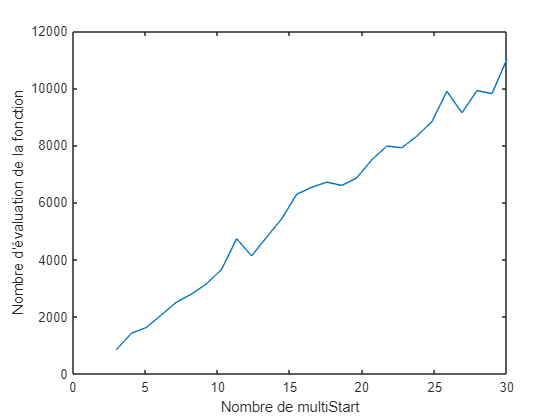

nombreMultiStart = linspace(3,30,nPoint);
figure()
plot (nombreMultiStart,funcCout);
ylabel("Nombre d'évaluation de la fonction");
xlabel("Nombre de multiStart");

Effectivement, l'évolution du nombre d'évaluation de la fonction objectif croit proportionnellement au paramatre n de multistart. Ceci est plutot intuitif.

On conserve n=10 pour ne pas avoir une resolution trop couteuse en temps.

Avec n=10, nombre d'évaluation de la fonction objectif est égal à 11558 alors qu'avec l'algorithme genetique, on obtient 6868. Ainsi, l'algorithme multistart est bien trop gourmand pour un résultat similaire. On aurait pu utiliser GlobalSearch

Essayons d'utiliser global search pour voir si les résultats sont plus concluants :

paramin = [0 0 0 0];
probleme = createOptimProblem('fmincon', 'x0', x0, 'objective', @(x) funCout(x, demande, production, cout, dureVieBatterie, rendement, n), 'lb',paramin);
% résolution par la methode globalsearch
gs = GlobalSearch();
[x_g, fval_g, exitflag_g, output_g, solutions_g] = run(gs, probleme);

GlobalSearch stopped because it analyzed all the trial points.

All 31 local solver runs converged with a positive local solver exit flag.


Cette methode semble plus interessante puisqu'elle nous propose un mix entre batterie et stockage hydrogène. Nous restons tout de même confus face à la diversité des résultats obtenus suivant le type de solveur utilisé.

# **2 - Résolution multiobjectif**

##     2.1) Test de la fonction multiobjectif

x0 = x;
[criteres] = multiCrit(x0, demande, production, cout, dureVieBatterie, rendement, n);

Error using opti_Smartgrid>multiCrit
Too many input arguments.

% coutInv représente le cout de l'investissement pour l'installation sur n années
coutInv = criteres(1)
taux_autoconsommation = criteres(2)

##     2.2) Résolution bi-objective

nvars = length(x0);
A = [];
b = [];
Aeq = [];
beq = [];
lb = [0 0 0 0]; % Pas de valeurs négatives
ub = [20, 20, 20, 20];
[x_multi, fval_multi, exitflag_multi, output_multi, population_multi, scores_multi] = gamultiobj(@(x) multiCrit(x, demande, production, cout,dureVieBatterie, rendement, n), nvars, A,b,Aeq,beq,lb,ub)%Solveur 1
[x_multi2, fval_multi2, exitflag_multi2, output_multi2, residuals_multi2] = paretosearch(@(x) multiCrit(x, demande, production, cout,dureVieBatterie, n), nvars, A,b,Aeq,beq,lb,ub)
plot(scores_multi(1,:), scores_multi(2,:))


Ci dessus, on essaye de tracer le front de paretto mais cette droite linéaire ne correspond pas à ce qu'on devrait observer. Nous restons donc mitigés.

# **3 - Fonction Objectif**

## **    3.1) Fonction mono-objectif **

**Fonction objectif : F𝑚𝑖𝑛 = 𝑆pv*𝐶pv + 𝑃el*𝐶el +𝑃pac * 𝐶pac + 𝑛 / 10 * 𝑄bat * 𝐶bat + 𝑛 * 𝑄ext_tot  * Cext**

function [couTot] = funCout(x, demande, production, cout, dureVieBatterie, rendement, n)
% initialisation des listes de quantité d'énergie
Qext = zeros(1,length(demande)); % quantité d'énergie achetée sur le réseau
Qbat = zeros(1,length(demande)); % stock d'énergie dans la batterie
Qh2 = zeros(1,length(demande)); % stock d'énergie dans la PAC
Qbat(1) = 0;
Qh2(1) = 0;
Qext(1) = demande(1) - production(1);
% chaque jour, maj de l'état du systeme
% x = [Spv, Pel, Ppac, Qbat]
for heure = 2:length(demande)
    excedent = production(heure)*x(1)-demande(heure);
    % Cas d'une surproduction PV
    if excedent >= 0
        Qbat(heure) = Qbat(heure-1) + min(excedent, x(4)-Qbat(heure-1));%Nouvelle quantité d'énergie = ancienne + l'excédent si la capacité le permet ou la maximum de ce que l'on peut remplir
        excedent2 = max(0, excedent-Qbat(heure)); % On définit un deuxième éxcèdant = soit 0 si tout à été pris en charge par la batterie, soit ce qu'il reste après avoir chargé la batterie au maximum
        nrjAElectrolyser = min(excedent2, x(2)); %Energie à stocker sous fpar le biai de l'electroliseur = excedent sauf si ce dernier dépasse la capacité de l'électrolyseur
        Qh2(heure) = Qh2(heure-1) + nrjAElectrolyser * rendement(1); %Energie stockée sous forme d'H2 = Energie déjà stockée + Energie issue de l'electrolieur (en prenant en compte le rendement de ce dernier)
        %Qext(heure) = nrjAElectrolyser - excedent2;  % <=0 car on revend l'excedent d'énergie au réseau
        Qext(heure) = 0;
    % Cas d'une sous-production PV
    else
        manque = -excedent; %on définit de sorte à ce qu'il reste positif dans nos formules
        nrjFourniBat = min(Qbat(heure - 1), manque); % Les batteries fournissent l'énergie nécéssaire pour combler le manque si elles le peuvent, sinon elles fournissent ce qu'elles le reste dans leurs réserves
        Qbat(heure) = Qbat(heure -1)-nrjFourniBat; % La quantitée d'énergie restante dans les batteries = ancienne moins l'énergie à fournir
        manque2 = max(0, manque-nrjFourniBat); % on définit un deuxième manque = différence entre le besoin initial et l'énergie qu'à pu fournir la batterie 
        nrjAFournirH2 = min(x(3),min(Qh2(heure-1)*rendement(2), manque2)); %L'énergie à fournir via notre réserve d'H2 = soit au manque si elle est en capacité de le fournir, soit à ce qui lui reste d'énergie stockée (en prenant en compte le rendement), soit au maximun de la capacité qu'elle est en mesure de délivrée (cas qui n'arrive que si les deux premiers sont supérieurs à la capacité maximale que peut fournir la pac en une heure)
        Qh2(heure) = Qh2(heure-1)-nrjAFournirH2 / rendement(2); %La quantité d'H2 restante = quantité précédente - l'énergie à fournir/rendement de la PAC
        Qext(heure) = manque2 - nrjAFournirH2;  % >=0 car on achete de l'énergie au réseau
    end
end
Qext_tot = sum(Qext');
couTot =   x(1)*cout(1) + x(2)*cout(2) + x(3)*cout(3) + ceil(n/dureVieBatterie) * x(4) * cout(4) + n * Qext_tot * cout(5); % CF fonction coût du sujet
end


## **    3.3) Fonction multiobjectif**

function [criteres] = multiCrit(x, demande, production, cout,dureVieBatterie, n)
coutInv =   x(1)*cout(1) + x(2)*cout(2) + x(3)*cout(3) + ceil(n/dureVieBatterie) * x(4) * cout(4); % CF fonction coût du sujet
% cout investissement des équipements seuls
% coutInv = x(1)*cout(1) + x(2)*cout(2) + x(3)*cout(3) + ceil(n/dureVieBatterie) * x(4) * cout(4);
% autoproduction calculée en faisant la moyenne des taux autoproduction de chaque heure
% On cherche à maximiser l'autoproduction donc on minimise -autoproduction
autoproduction = -sum(production./demande)/length(demande);
criteres = [coutInv, autoproduction];
end